A = [0 1; -8 -6]

A =      0     1
    -8    -6


B = [0 1]'

B =      0
     1


C = [1 0]

C =      1     0


D = 0

D = 0

sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2
   x1   0   1
   x2  -8  -6
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



x0 = [1 0]'

x0 =      1
     0


config = RespConfig("InitialState",x0)

Unrecognized function or variable 'RespConfig'.

figure
step(sys,config)
grid on

t = 0:0.01:4;
y = 1/8 + (7/4)*exp(-2*t)-(7/8)*exp(-4*t)

y =     1.0000    0.9997    0.9987    0.9970    0.9948    0.9921    0.9888    0.9851    0.9809    0.9763    0.9712    0.9659    0.9602    0.9541    0.9478    0.9412    0.9344    0.9273    0.9200    0.9125    0.9049    0.8971    0.8891    0.8810    0.8728    0.8645    0.8561    0.8477    0.8391    0.8305    0.8219    0.8132    0.8045    0.7957    0.7870    0.7783    0.7695    0.7608    0.7520    0.7433    0.7347    0.7260    0.7174    0.7089    0.7003    0.6919    0.6834    0.6751    0.6668    0.6585


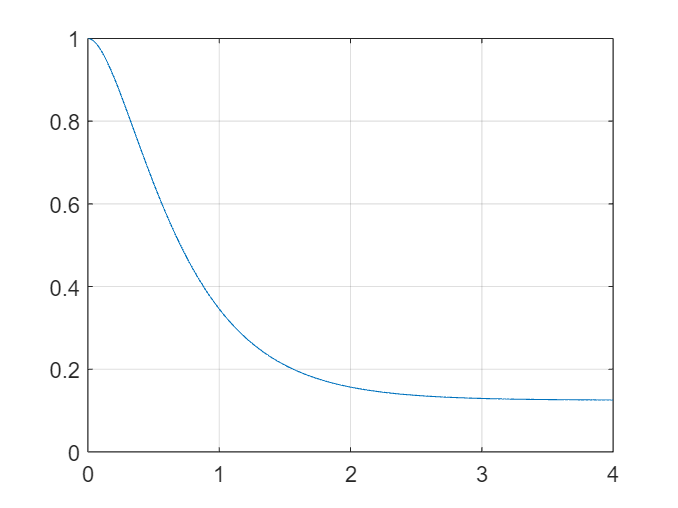

plot(t,y)
grid on